# Transient Heat Conduction: Timestepping

clear all, close all, clc
set_defaults()

To determine the cooling timescale of the the cryomagma chamber beneath Occator crator we need to solve the transient heat condution problem. Hence we are interested in the following Initial and Boundary Value Problem (IBVP)

PDE:    $\rho c_p\frac{\partial T}{\partial t}-\nabla\cdot\left[\kappa \nabla T\right] = f_s$   on  $\mathbf{x}\in \Omega$

BC:     $T(\mathbf{x},t) = T_b(\mathbf{x})$                  on $\mathbf{x}\in \partial\Omega_D$

IC:       $T(\mathbf{x},0) = T_0(\mathbf{x})$                 on  $\mathbf{x}\in \Omega$

For the moment we assume that $c_p$ and $\kappa$ are independent of temperature, so that the problem is linear.  However, both $c_p$ and $\kappa$ can vary with location due to differences in material. The discretization of the spatial derivative is identical to the steady problem so tha

$-\nabla\cdot\left[\kappa \nabla T\right] \approx \mathbf{L}\mathbf{u}$,

where `L``=-``D``*``Kd``*``G` and `u` the vector of unknown temperatures. Below we'll discuss a common time discretization.

## Theta Method

To discretize the time derivative we use a finite difference


$$\frac{\partial T}{\partial t} \approx \frac{\mathbf{u}^{n+1}-\mathbf{u}^n}{\Delta t}$$


where the superscript $n$ denotes the time level and $\Delta t = t^{n+1}-t^n$. So the discretized equations becomes

$\mathbf{M}\left(\mathbf{u}^{n+1}-\mathbf{u}^n\right)+\Delta t\,\mathbf{L}\mathbf{u}^{?} =\Delta t\, \mathbf{f}_s$,

where $\mathbf{M}$ is a N by N diagonal *mass matrix* with the values of $\rho c_p$ in each cell on the diagonal, where N is the number of unknowns. The properties of the time integrations are determined by choosing the time level at which $\mathbf{u}^{?}$ is evaluated. In the theta-method we introduce a paramter $\theta
$ that allows us to determine the time level as follows

$\mathbf{u}^{?} = \theta \mathbf{u}^n+(1-\theta) \mathbf{u}^{n+1}$ (note some textbooks flip in this definition, we are following [Iserles](https://www.cambridge.org/core/books/first-course-in-the-numerical-analysis-of-differential-equations/2B4E05F5CFC58CFDC7BBBC6D1150661B))

Substituting into the discrete equation


$$\mathbf{M}\left(\mathbf{u}^{n+1}-\mathbf{u}^n\right)+\Delta t\,\mathbf{L}\left( \theta \mathbf{u}^n+(1-\theta) \mathbf{u}^{n+1}\right) =\Delta t\, \mathbf{f}_s$$


Collecting the unknown terms on the left and the known terms on the right


$$\mathbf{IM}\, \mathbf{u}^{n+1} = \mathbf{EX}\,\mathbf{u}^n+\Delta t\,\mathbf{f}_s$$


where we have the following implicit and explicit matrices

$\mathbf{IM} = \mathbf{M} + (1-\theta) \Delta t\, \mathbf{L}$,

$\mathbf{EX} = \mathbf{M} - \theta \Delta t  \,\mathbf{L}$.

Note that the specifics of the PDE are hiden in **L**, therefore the theta-method can be applied to **any **transient linear equation.  

clf
rho = 1e3;
cp = 2e3;
kappa = 4;
Diff = kappa/(rho*cp);

Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = 50;
Grid = build_grid(Grid);
[D,G,~,I,M] = build_ops(Grid);
L = -D*Diff*G; M = I;
IM = @(theta,dt) M + (1-theta)*dt*L;
EX = @(theta,dt) M - theta*dt*L;

## Amplification Matrix

In the absence of boundary conditions or source terms driving the problem, we expect temperature variations to decline and the temperature to become constant across the domain. For $\mathbf{f}_s=0$ we can write


$$\mathbf{u}^{n+1} = \mathbf{IM}^{-1}\mathbf{EX}\,\mathbf{u}^n$$



$$\mathbf{u}^{n+1} = \mathbf{A}\,\mathbf{u}^n$$


where $\mathbf{A} = \mathbf{IM}^{-1}\mathbf{EX}$ is the amplification matrix. The solution at the $n$-th timestep is therefore


$$\mathbf{u}^n = \mathbf{A}^n\mathbf{u}^0$$


where $\mathbf{u}^0$ is the initial condition. Using the spectral decomposition of symmetric matrices we can write


$$\mathbf{A} = \mathbf{Q}\mathbf{\Lambda}\mathbf{Q}^{-1}$$


where $\mathbf{Q}$ is the square matrix where the eigenvectors of $\mathbf{A}$ are the columns and $\mathbf{\Lambda}$ is a diagonal matrix containing the eigenvalues $\lambda$ of $\mathbf{A}$. Since $\mathbf{Q}^{-1}\mathbf{Q}=\mathbf{I}$, we see that the $n$-th power of a matrix is

$\mathbf{A}^n = \mathbf{Q}\mathbf{\Lambda}^n\mathbf{Q}^{-1}$,

is simply computed by raising the eigenvalues to the $n$-th power.

**Example: Spectral decomposition of the discrete Laplacian**

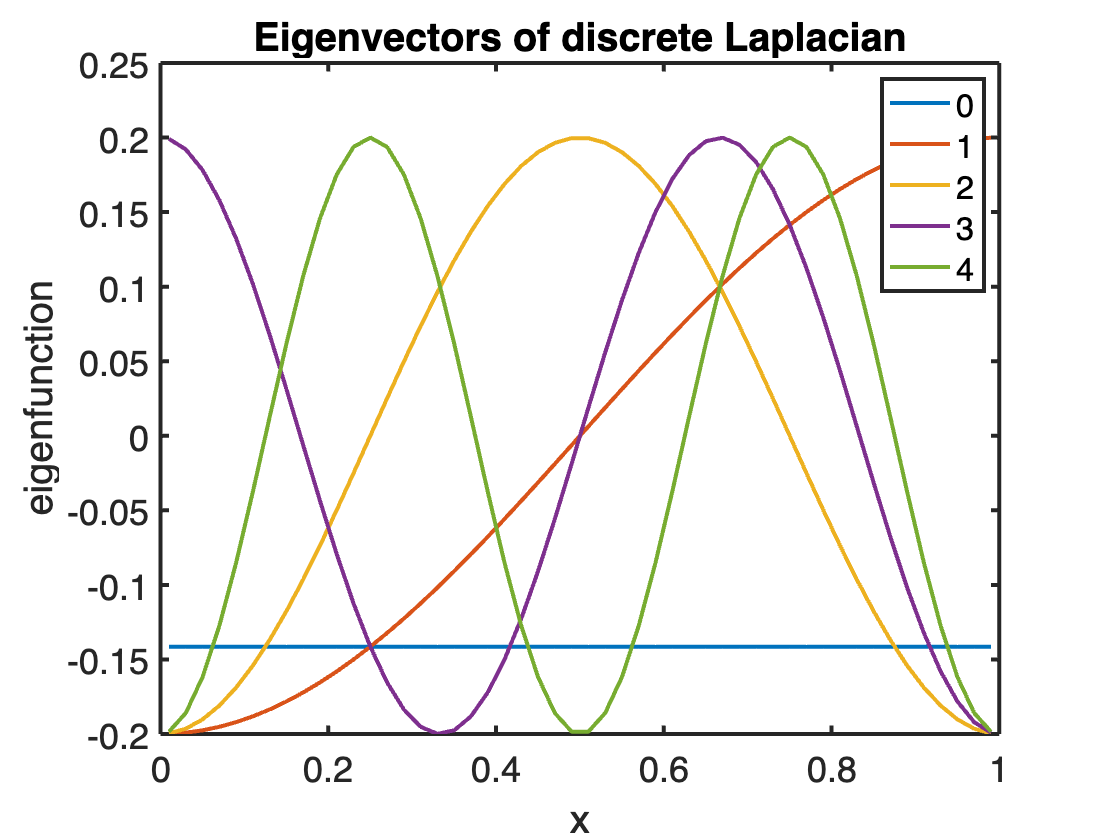

[Q,Lambda] = eig(full(L)); lam = diag(Lambda);
subplot 121
clf
for i=1:5
    plot(Grid.xc,Q(:,i)), hold on
end
title('Eigenvectors of discrete Laplacian')
xlabel 'x'
ylabel 'eigenfunction'
legend('0','1','2','3','4')
pbaspect([1 .8 1])

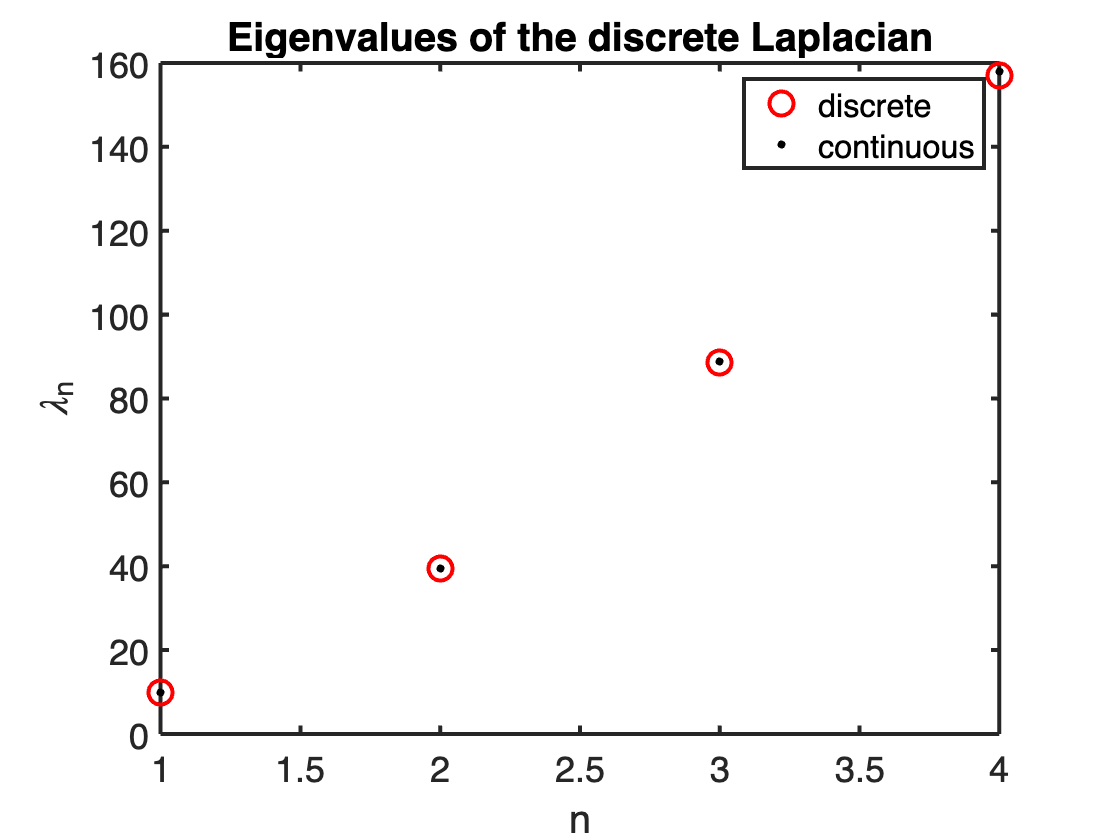


subplot 122
clf
scale = (pi/Grid.Lx).^2/lam(2); % I am not sure why we need this scaling
for n = 1:4;
    plot(n,scale*lam(n+1),'ro'), hold on
    plot(n,(n*pi/Grid.Lx).^2,'k.')
end
title('Eigenvalues of the discrete Laplacian')
xlabel 'n'
ylabel '\lambda_n'
legend('discrete','continuous')
pbaspect([1 .8 1])

In GEO 366M Mathematical Methods in Geophysics you will learn/have learned that the eigenvalues, $\lambda_n$, and eigenvectors, $\varphi_n(x)$, of the Laplacian, $\nabla^2(\bullet)$ are

- 
$$\lambda_n=\left(\frac{n\pi}{H}\right)^2$$


- 
$$\varphi_n=\cos\left(\sqrt{\lambda_n}x\right)$$


In GEO 366M you will also show that the analytic solution to a heat conduction problem has the form

$T(x,t) = \sum_{n=0}^\infty a_n\varphi_n(x)\mathrm{e}^{-\lambda_n D_t t}$,

where the coefficients $a_n$ depend of the initial condition and $D_t = \frac{\kappa}{\rho c_p}$ is the thermal diffusivity. The general solution shows that increasing oscillatory functions decay increasingl rapidly. This makes physical sense, a diffusive process like heat conduction smoothes the solution rapidly.

Similarly the evolution of the discrete solution, `u`, will depend on the eigenvalues of the amplification matrix `A` (different from `L`!). For a stable numerical method all $\lambda_n(\mathbf{A}) \leq|1|$.  Below we show that the magnitude of the eigenvalues of `A` changes significantly with $\theta
$.

*Note: For some reasons the eigenvalues need to be scaled - not sure why that is. Also there is an error in the eigenvalues that increases with n. So if the larger ones are off just increase Nx until the respective eigen function is resolved!*

## Properties of the Theta-Method

**Forward Euler (FE): **$\theta = 1$

In this case, we have the following matrices

$\mathbf{IM} = \mathbf{M} $,

$\mathbf{EX} = \mathbf{M} -  \Delta t  \,\mathbf{L}$,

since $\mathbf{M} $is diagonal no matrix has to be inverted to compute the next timestep and the method is called *explicit*. Explicity timesteps are simple to implement and computationally cheap. However, we will show below that typically need very many of them.

Relative to the transport, **Lu**, which is evaluated at $t^n$, the time derivative is discretized with a one-sided derivative. Therefore, it can be shown that the Forward Euler Method is first-order accurate, i.e, $\mathcal{O}(\Delta t)$. 

To understand the stability of the FE-method we plot $\min_n(\lambda_n)$ and $\max_n(\lambda_n)$ of the amplification matrix, `A`,as function of $\Delta t$.

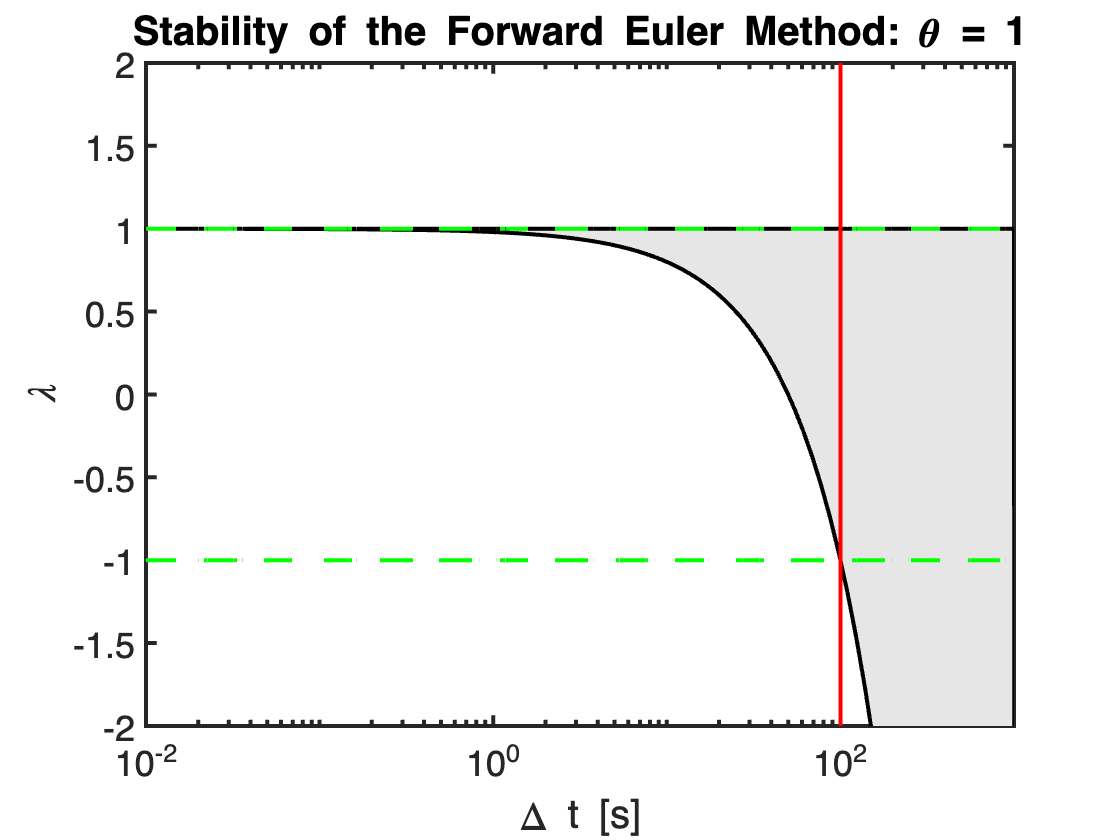

theta = 1;
dt_max = Grid.dx^2/(2*Diff);
dt_vec = logspace(-2,3,1e2);

figure
for i = 1:length(dt_vec)
    A = inv(IM(theta,dt_vec(i)))*EX(theta,dt_vec(i));
    lam = eig(full(A));
    lam_max_FE(i) = max(lam);
    lam_min_FE(i) = min(lam);
end
semilogx(dt_vec,lam_max_FE,'k'), hold on
patch([dt_vec,fliplr(dt_vec)],[lam_max_FE,fliplr(lam_min_FE)],0.9*[1 1 1]), hold on
semilogx(dt_vec,lam_min_FE,'k')
semilogx(dt_vec,ones(size(dt_vec)),'g--','linewidth',2)
semilogx(dt_vec,-ones(size(dt_vec)),'g--','linewidth',2)
semilogx(dt_max*[1 1],[-2 2],'r','linewidth',2), hold off
xlim([1e-2 1e3]), ylim([-2 2])
xlabel '\Delta t [s]'
ylabel('\lambda')
title 'Stability of the Forward Euler Method: \theta = 1'

As $\Delta t$ increases the stability condition, $\lambda_n(\mathbf{A}) \leq|1|$, so that the FE-method is only *conditionally stable*. The FE-method is only stable (does not blow up) under the condition

$\Delta t_N\leq\frac{\Delta x^2}{2 D_t}$ (Neumann condition)

where $D_t = \frac{\kappa}{\rho c_p}$ is the thermal diffusivity. A smart chap called [John Von Neumann](https://en.wikipedia.org/wiki/John_von_Neumann) figure this one out - personal hero of mine. The physical interpretation of this condition is that $\Delta t_N$ is the time required for the temperature to diffuse across one grid block.

For thermal conduction the timestep limit declines rapidly with grid spacing

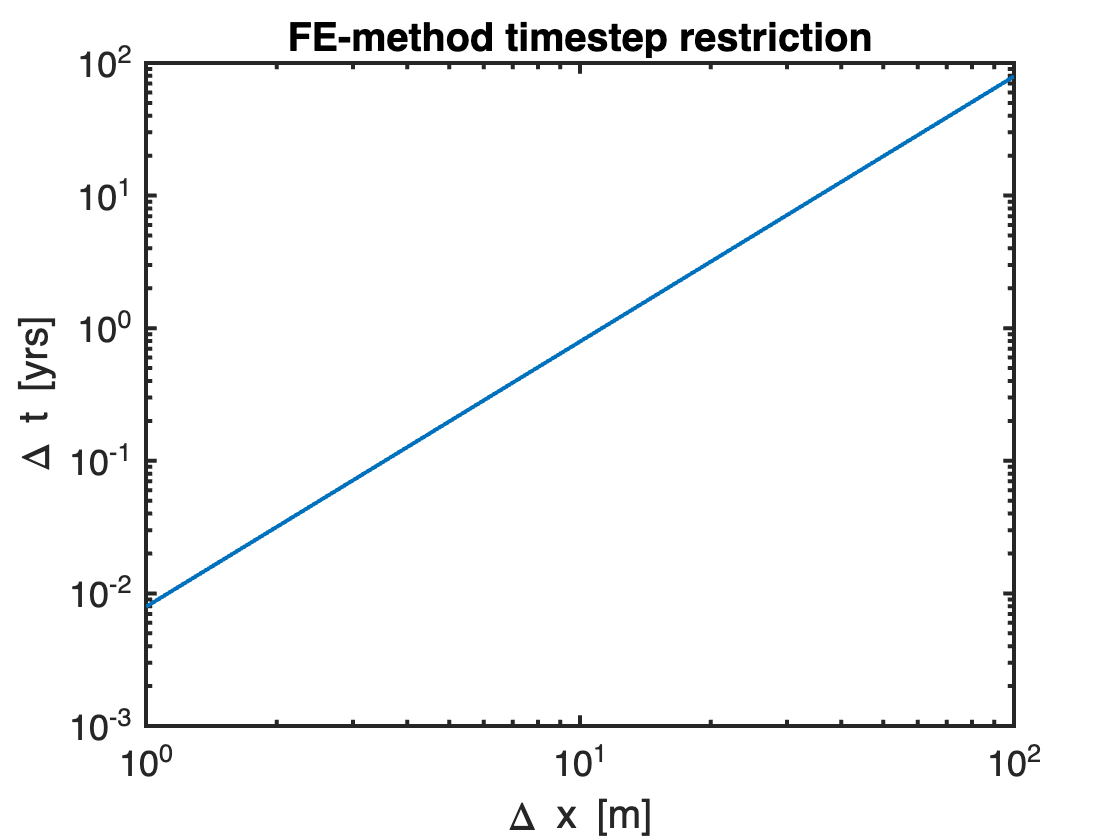

dx_vec = logspace(0,2,1e2);
s2yr = 60^2*24*365;
loglog(dx_vec,dx_vec.^2/(2*Diff)/s2yr);
xlabel '\Delta x [m]', ylabel '\Delta t [yrs]'
title 'FE-method timestep restriction'

Therefore, the Forward Euler method is typically not efficient for solving the heat equation. 

**Backward Euler (BE):** $\theta = 0$

In this case, we have the following matrices

$\mathbf{IM} = \mathbf{M} + \Delta t\, \mathbf{L}$,


$$\mathbf{EX} = \mathbf{M} $$


so that $\mathbf{IM}$ is not diagonal and a linear system must be solved at every time step. A timestepping methos that requires solution of a linear system is called *implicit*. 

Relative to the transport, **Lu**, which is evaluated at $t^{n+1}$, the time derivative is discretized with a one-sided derivative. Therefore, it can be shown that the Backward Euler Method is also first-order accurate, i.e, $\mathcal{O}(\Delta t)$. 

To understand the stability of the BE-method we plot $\min_n(\lambda_n)$ and $\max_n(\lambda_n)$ of the amplification matrix, `A`,as function of $\Delta t$.

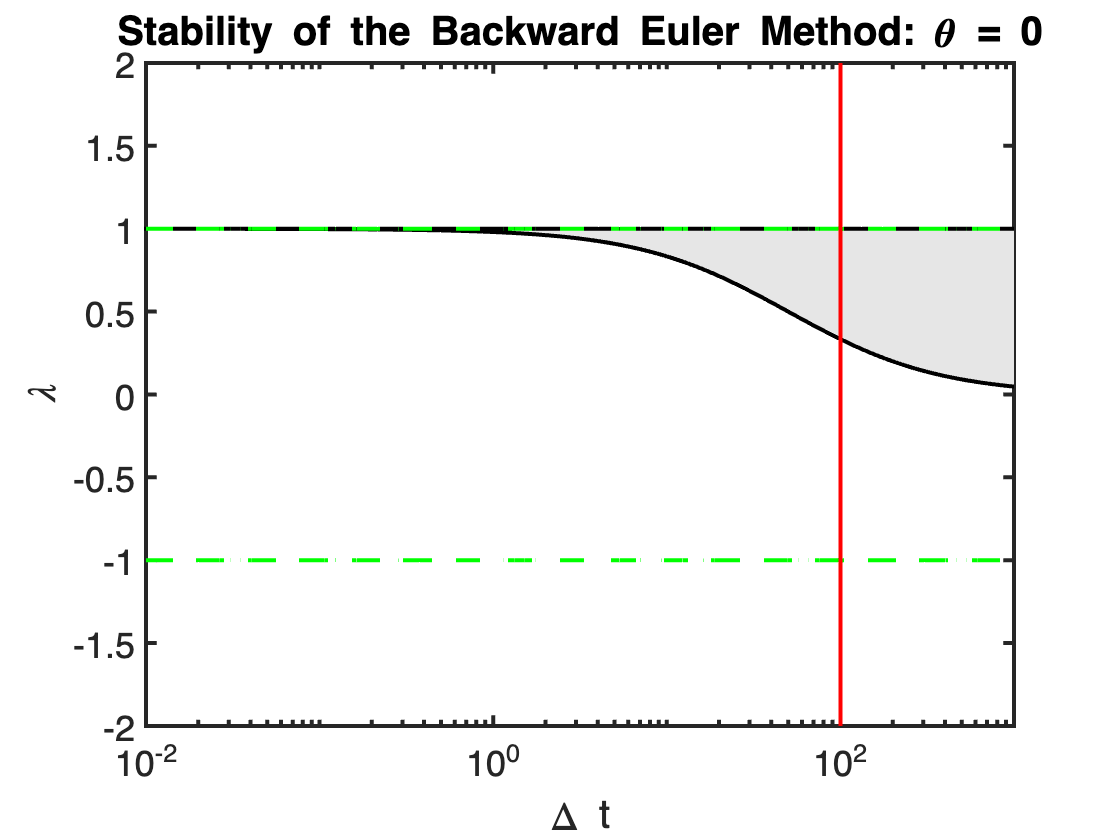

theta = 0;
dt_vec = logspace(-2,4,1e2);

figure
for i = 1:length(dt_vec)
    A = inv(IM(theta,dt_vec(i)))*EX(theta,dt_vec(i));
    lam = eig(full(A));
    lam_max_BE(i) = max(lam);
    lam_min_BE(i) = min(lam);
end
semilogx(dt_vec,lam_max_BE,'k'), hold on
patch([dt_vec,fliplr(dt_vec)],[lam_max_BE,fliplr(lam_min_BE)],0.9*[1 1 1]), hold on
semilogx(dt_vec,lam_min_BE,'k')
semilogx(dt_vec,ones(size(dt_vec)),'g--','linewidth',2)
semilogx(dt_vec,-ones(size(dt_vec)),'g--','linewidth',2)
semilogx(dt_max*[1 1],[-2 2],'r','linewidth',2), hold off
xlim([1e-2 1e3]), ylim([-2 2])
xlabel '\Delta t'
ylabel('\lambda')
title 'Stability of the Backward Euler Method: \theta = 0'

We see that the stability condition is always satisfied and it can be shown that  $0\leq\lambda_n(\mathbf{A}) \leq|1|$for the BE-method. This implies that the BE-method is *unconditionally stable*. This means you can take timesteps as large as you like and the computation will not blow up, but it will -of course - become increasingly less accurate. In general, the BE-method is the most robust and should be the first choice if you solve complicated problems.

**Crank-Nicholson (CN): **$\theta = \frac{1}{2}$

In this case, we have the following matrices

$\mathbf{IM} = \mathbf{M} + \frac{\Delta t}{2}\, \mathbf{L}$,

$\mathbf{EX} = \mathbf{M} - \frac{\Delta t}{2}  \,\mathbf{L}$.

Similar to the BE-method the CN-method is implicit and each time step requires the inversion of a linear system. 

Beacuse, the transport term, Lu, is evaluated at $t^{n+1/2}$the time-discretization is a central finite difference. Therefore, it can be shown that the CN-method is also first-order accurate, i.e, $\mathcal{O}(\Delta t^2)$. 

To understand the stability of the CN-method we plot $\min_n(\lambda_n)$ and $\max_n(\lambda_n)$ of the amplification matrix, `A`,as function of $\Delta t$.

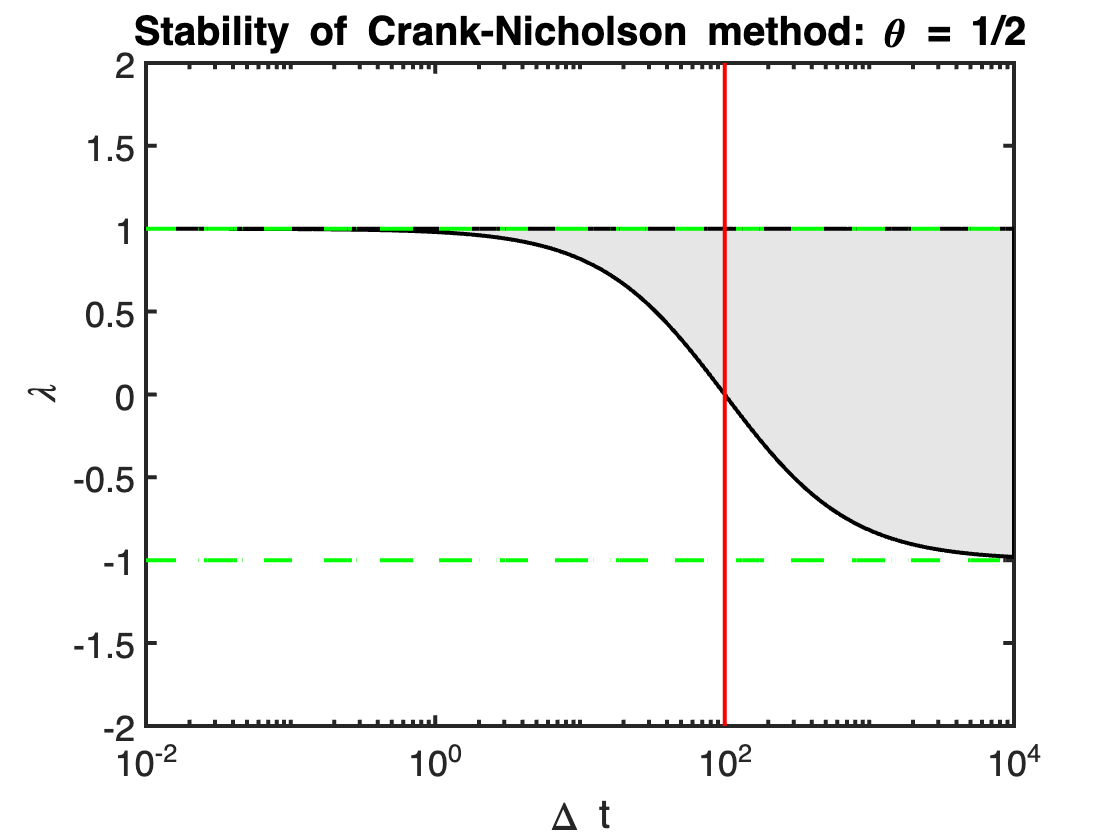

theta = 0.5;
dt_vec = logspace(-2,4,1e2);

figure
for i = 1:length(dt_vec)
    A = inv(IM(theta,dt_vec(i)))*EX(theta,dt_vec(i));
    lam = eig(full(A));
    lam_max_CN(i) = max(lam);
    lam_min_CN(i) = min(lam);
end
semilogx(dt_vec,lam_max_CN,'k'), hold on
patch([dt_vec,fliplr(dt_vec)],[lam_max_CN,fliplr(lam_min_CN)],0.9*[1 1 1]), hold on
semilogx(dt_vec,lam_min_CN,'k')
semilogx(dt_vec,ones(size(dt_vec)),'g--','linewidth',2)
semilogx(dt_vec,-ones(size(dt_vec)),'g--','linewidth',2)
semilogx(dt_max*[1 1],[-2 2],'r','linewidth',2), hold off
ylim([-2 2])
xlabel '\Delta t'
ylabel('\lambda')
title 'Stability of Crank-Nicholson method: \theta = 1/2'

We can see that the stability condition, $\lambda_n(\mathbf{A}) \leq|1|$, is satisfied for all $\Delta t$, so that the CN-method is unconditionally stable. However, note that the eigenvalues become negative at  the Neumann condition for the FE-method. Once the amplification matrix has negative eigenvalues, oscillation *may* occur in the CN-method. The oscillations are not unstable, i.e., they don't blow up, they just make you think you screwed up. In my experience, no oscillations occur if the IC and the BC's don't introduce kinks in the solution. However, I often solve problems with temperature kinks and so I typically use the BE-method.

In general, first solve the problem with the BE-method. Only once everything works, switch to the CN-method to gain the additional accuracy. If the switch introduces oscillations, you have to reduce the timestep or smooth the IC. Sometimes it is sufficient to solve one time step with the BE method, which gets rid of all kinks, and then switch to the CN-method.

## Solving the transient problem

This is just a simple example, the decay of local heated region.

tmax = 1e4;
Nt = 15; 
dt = tmax/Nt;
fprintf('dt/dt_N = %3.2e.\n',dt/dt_max)

dt/dt_N = 6.67e+00.


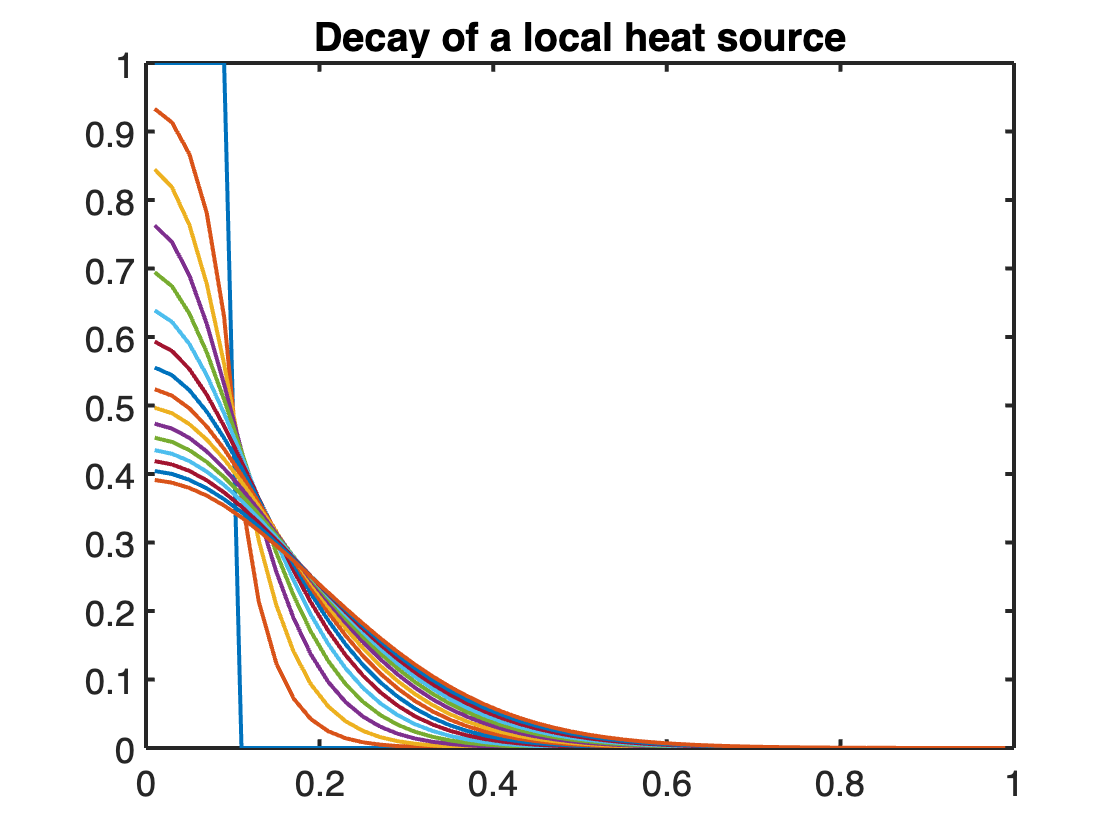

theta = 0;
Im = IM(theta,dt); Ex = EX(theta,dt);
u = zeros(Grid.Nx,1); u(Grid.xc<=.1) = 1;

time = 0;
figure 
plot(Grid.xc,u,'-'), hold on
for i = 1:Nt
    time = time + dt;
    u = solve_lbvp(Im,Ex*u,[],[],I);
    plot(Grid.xc,u,'-'), drawnow
end
hold off
title 'Decay of a local heat source'

## Oscillation in CN-Method

The Crank-Nicholson method can lead to oscillations when the higher-order assumed in the temporal discretization is violated by a discontinuous initial or boundary condition, as illustrated by the three examples below.

theta = .5;
u0 = zeros(Grid.Nx,1); u0(Grid.xc<=.1) = 1;
% u = cos(2*pi*Grid.xc);

**Exmple 1:** If the initial condition is not smooth, an oscillation-free solution is only guaranteed for $dt\leq dx^2/(2D)$. For larger time steps the solution can become oscillatory at early times as illustrated in the example below. In contrast to the explicit timestep these oscillation do not grow exponentially because $|\lambda|\leq 1$(see above). As shown in the example these oscillations disappear over time as the solution becomes more smooth.

dt = 5*dt_max; % Nx = 50
Nt = ceil(tmax/dt); 
fprintf('dt/dt_N = %3.2e.\n',dt/dt_max)

dt/dt_N = 5.00e+00.


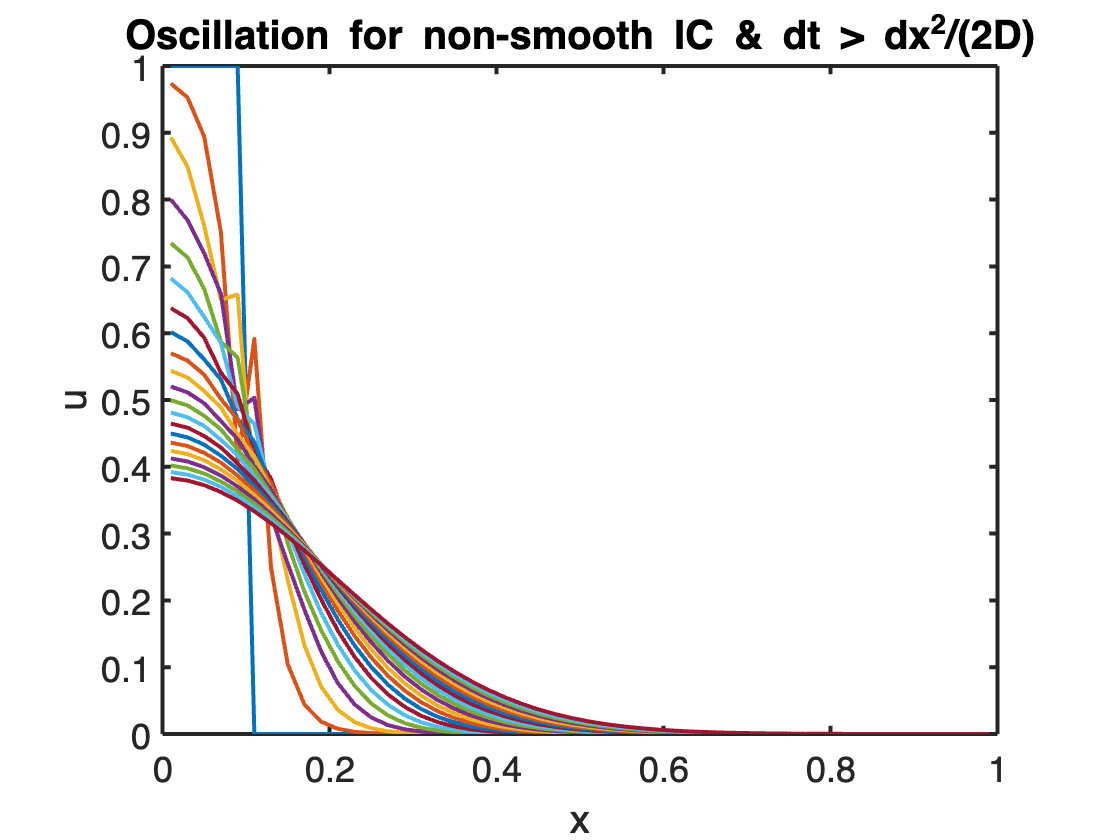

Im = IM(.5,dt); Ex = EX(.5,dt); u = u0;

figure 
plot(Grid.xc,u,'-'), hold on
for i = 1:Nt
    u = solve_lbvp(Im,Ex*u,[],[],I);
    plot(Grid.xc,u,'-'), drawnow
end
hold off
title 'Oscillation for non-smooth IC & dt > dx^2/(2D)'
xlabel 'x'
ylabel 'u'
pbaspect([1 .8 1])

**Example 2: **Below is an example with the citical timeste, $dt = dx^2/(2D)$, where the solution remains smooth despite the discontinuous initial condition.

dt = 1*dt_max;
Nt = ceil(tmax/dt); 
fprintf('dt/dt_N = %3.2e.\n',dt/dt_max)

dt/dt_N = 1.00e+00.


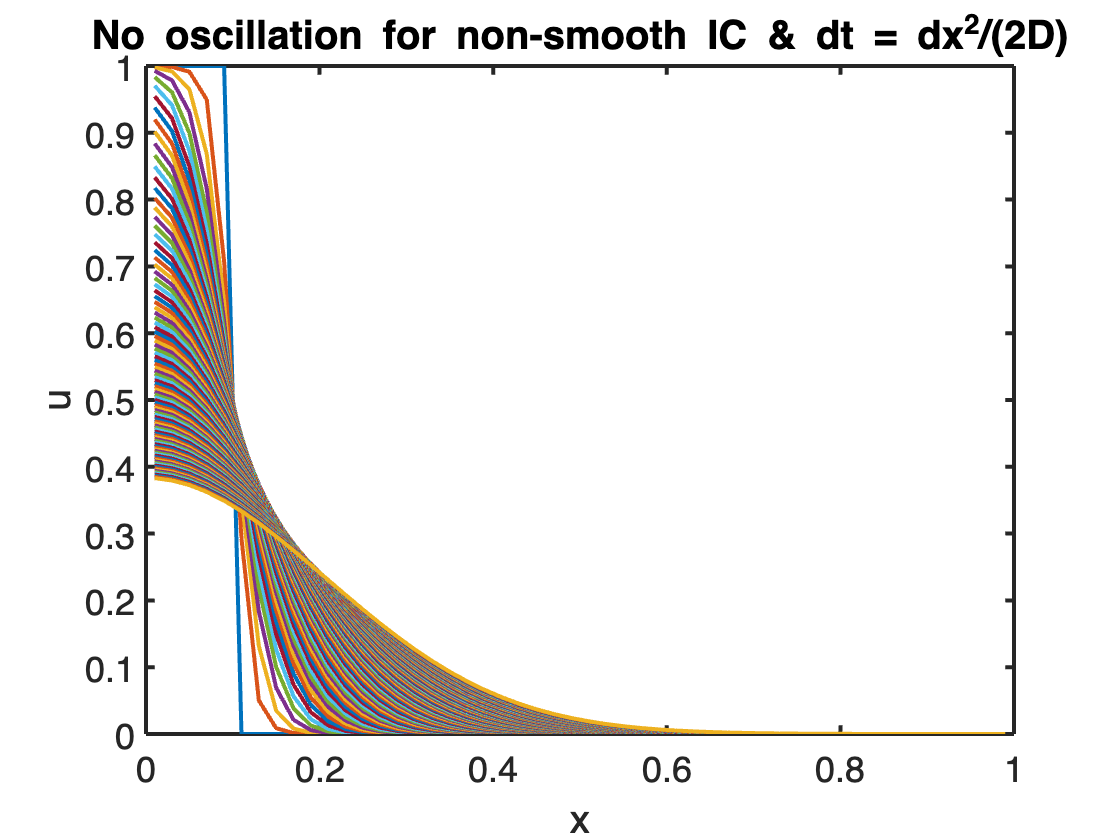

Im = IM(.5,dt); Ex = EX(.5,dt); u = u0;

figure
plot(Grid.xc,u,'-'), hold on
for i = 1:Nt
    time = time + dt;
    u = solve_lbvp(Im,Ex*u,[],[],I);
    plot(Grid.xc,u,'-'), drawnow
end
hold off
title 'No oscillation for non-smooth IC & dt = dx^2/(2D)'
xlabel 'x'
ylabel 'u'

Example 3: Here we illustrate that the solution remais smooth if the initial condition is smooth, even if the timestep exceeds the conditon $dt > dx^2/(2D)$. Of course, the same is true for smaller timesteps.

dt = 5*dt_max;
Nt = ceil(tmax/dt); 
fprintf('dt/dt_N = %3.2e.\n',dt/dt_max)

dt/dt_N = 5.00e+00.


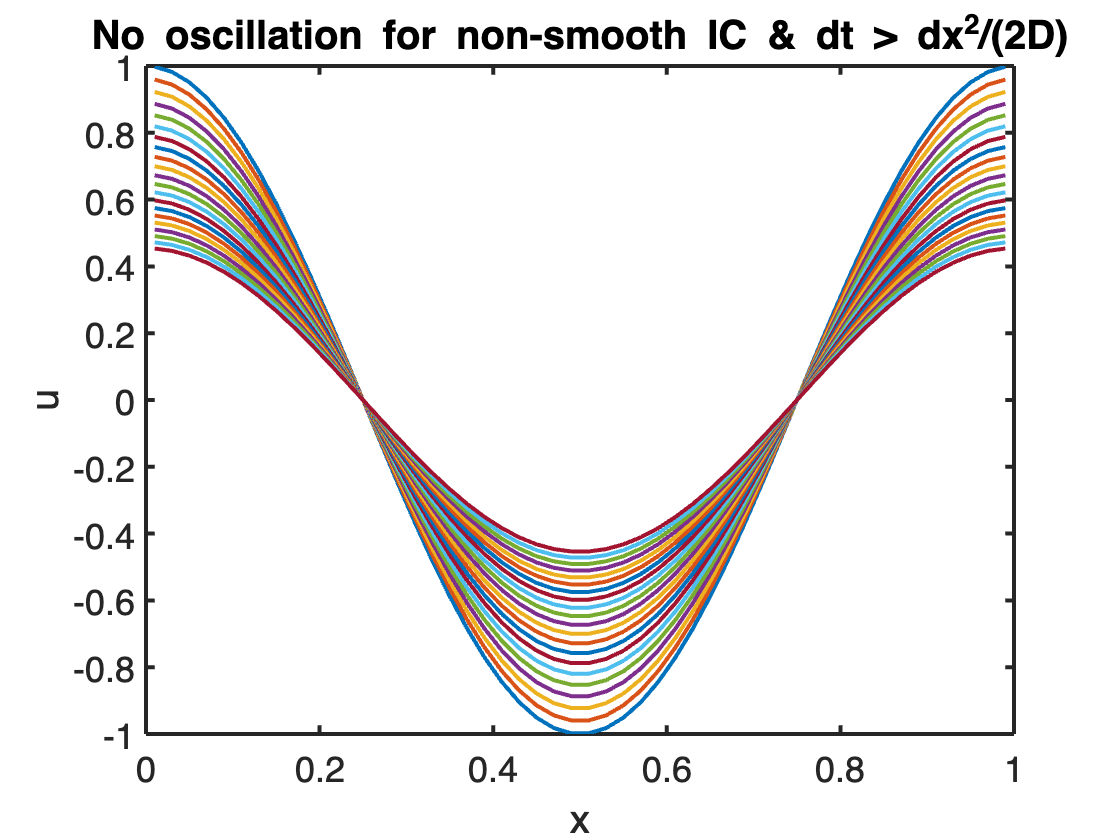

Im = IM(.5,dt); Ex = EX(.5,dt); 
u = cos(2*pi*Grid.xc);

figure
plot(Grid.xc,u,'-'), hold on
for i = 1:Nt
    time = time + dt;
    u = solve_lbvp(Im,Ex*u,[],[],I);
    plot(Grid.xc,u,'-'), drawnow
end
hold off
title 'No oscillation for non-smooth IC & dt > dx^2/(2D)'
xlabel 'x'
ylabel 'u'

# Auxillary functions

## set_defaults()

function [] = set_defaults()
    set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end
